## Homework 5

**朱灏轩 2411374**

### Question

Find out the wavelength for $\text{GaAs}$/$\text{GaAlAs}$ quantum well.

- Calculate the ground-state energies of the electron and hole

- Calculate the energy gap and emission wavelength

#### Tips

- Use the program for finite square well as a reference, $L_2$ can be set to $48\text{nm}$

- Use atomic unit: $E_{h}=27.211\ \text{eV}$, $a_{0}=0.0529\ \text{nm}$

- Relation between the wavelength and the energy of a photon: $\left\{ \begin{array}{l}
E=h\nu=h\frac{c}{\lambda} \\
\lambda = \frac{hc}{E},\ hc = 1240\ \text{eV}\cdot\text{nm}
\end{array} \right.$

- Get correct $H
$, be careful to the elements at the boundry

### Solution

设定公共参数

% General parameters
N = 109;                            % Sampling points number
lmax = 11;                          % Maximum coord
Lmax = 2 * lmax;
h = Lmax / (1+N);                   % Sampling interval
i = 1:N;                            % Sampling points index
x = (i - (N + 1) / 2) .* h;         % Sampling points coords
wellLeftIndex = (N+1) / 2 - 1 / h;  % Well left edge coord index
wellRightIndex = (N+1) / 2 + 1 / h; % Well right edge coord index
V0 = 48;                            % Well depth, [nm]

设定电子及空穴质量，在$\text{GaAs}$中，电子的有效质量为$0.067$，空穴的有效质量为$0.45$

% Effective mass of electrons and holes in GaAs
me = 0.067; % Effective mass of an electron
mh = 0.45; % Effective mass of a hole

针对电子及空穴构建 $H$ 矩阵

% Create upper and lower diagonal elements, avoid loop for performance 
offDiag = diag(repmat([-1], 1, N-1), 1) + diag(repmat([-1], 1, N-1), -1);
% Create H matrix for electrons and holes
H_e = eye(N, N) .* (2 + 2 * h^2 * V0) + offDiag;
H_h = eye(N, N) .* (2 + 2 * h^2 * V0) + offDiag;
% Create boundry conditions for the well
for i = wellLeftIndex+1:wellRightIndex-1
    H_e(i, i) = 2;
    H_h(i, i) = 2;
end

$H$ 矩阵归一化

% Normalize H matrix
H_e = H_e / (2 * me * h^2);
H_h = H_h / (2 * mh * h^2);

求解 $H$ 矩阵特征值

% Electron
[V_e, D_e] = eig(H_e);
eigenvalues_e = sort(diag(D_e));
GroundEnergy_e = eigenvalues_e(1);
% Hole
[V_h, D_h] = eig(H_h);
eigenvalues_h = sort(diag(D_h));
GroundEnergy_h = eigenvalues_h(1);

定义物理常数

% Constants
h_planck = 6.62607015e-34;    % [J·s]
c_light = 3e8;                % [m/s]
eV_to_J = 1.602176634e-19;    % [J/eV]
E_h = 27.211;                 % [eV]
a_0=0.0529;                   % [nm]

计算基态能量、能隙宽度及发射波长

% Energy gap and emission wavelength
Delta_E = GroundEnergy_e - GroundEnergy_h;            % eV
lambda = (h_planck * c_light) / (Delta_E * eV_to_J);  % m
lambda_nm = lambda * 1e9;                             % nm

输出计算结果，此处结果以 SI 制单位及原子单位呈现

% Output
fprintf('电子基态能量: %.4f eV\n', GroundEnergy_e);

电子基态能量: 16.8110 eV


fprintf('电子基态能量: %.4f E_h\n', GroundEnergy_e / E_h);

电子基态能量: 0.6178 E_h


fprintf('空穴基态能量: %.4f eV\n', GroundEnergy_h);

空穴基态能量: 2.5030 eV


fprintf('空穴基态能量: %.4f E_h\n', GroundEnergy_h / E_h);

空穴基态能量: 0.0920 E_h


fprintf('能隙: %.4f eV\n', Delta_E);

能隙: 14.3080 eV


fprintf('能隙: %.4f E_h\n', Delta_E / E_h);

能隙: 0.5258 E_h


fprintf('发射波长: %.2f nm\n', lambda_nm);

发射波长: 86.71 nm


fprintf('发射波长: %.2f a_0\n', lambda_nm / a_0);

发射波长: 1639.20 a_0


绘制波函数

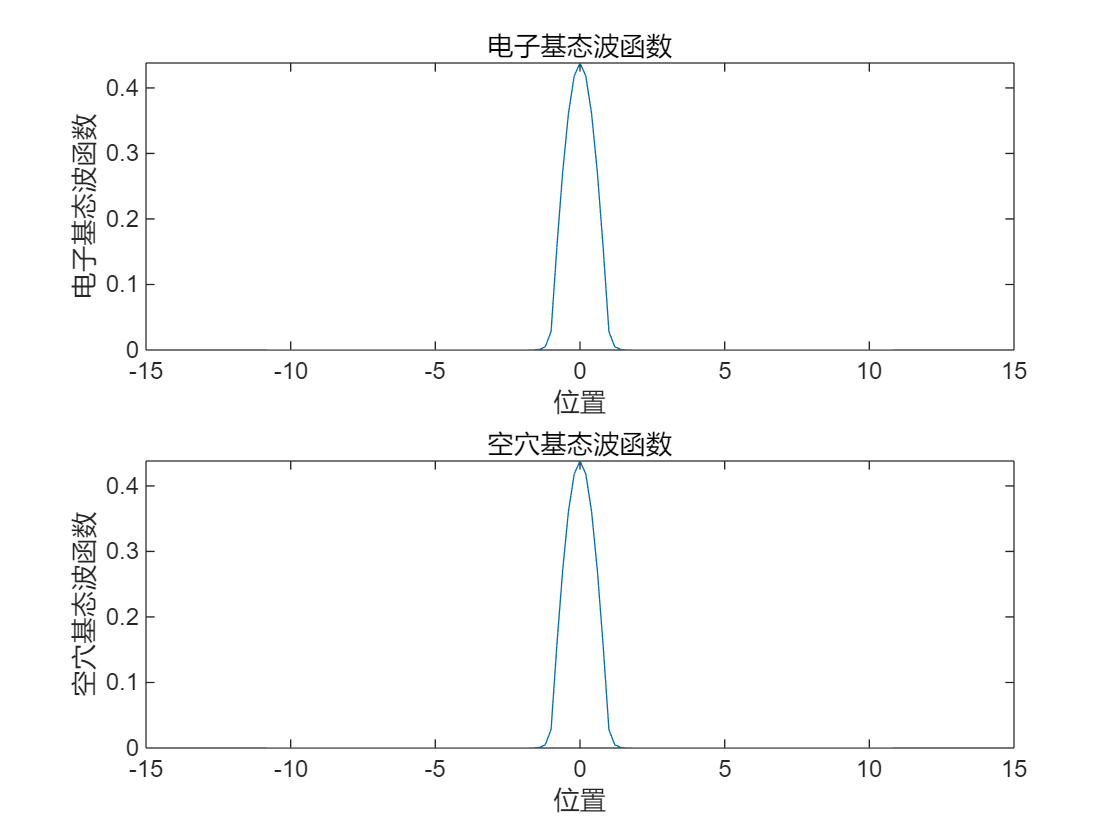

% Plot ground state energies
figure;
subplot(2,1,1);
plot(x, V_e(:,1));
xlabel('位置');
ylabel('电子基态波函数');
title('电子基态波函数');

subplot(2,1,2);
plot(x, V_h(:,1));
xlabel('位置');
ylabel('空穴基态波函数');
title('空穴基态波函数');

绘制能隙

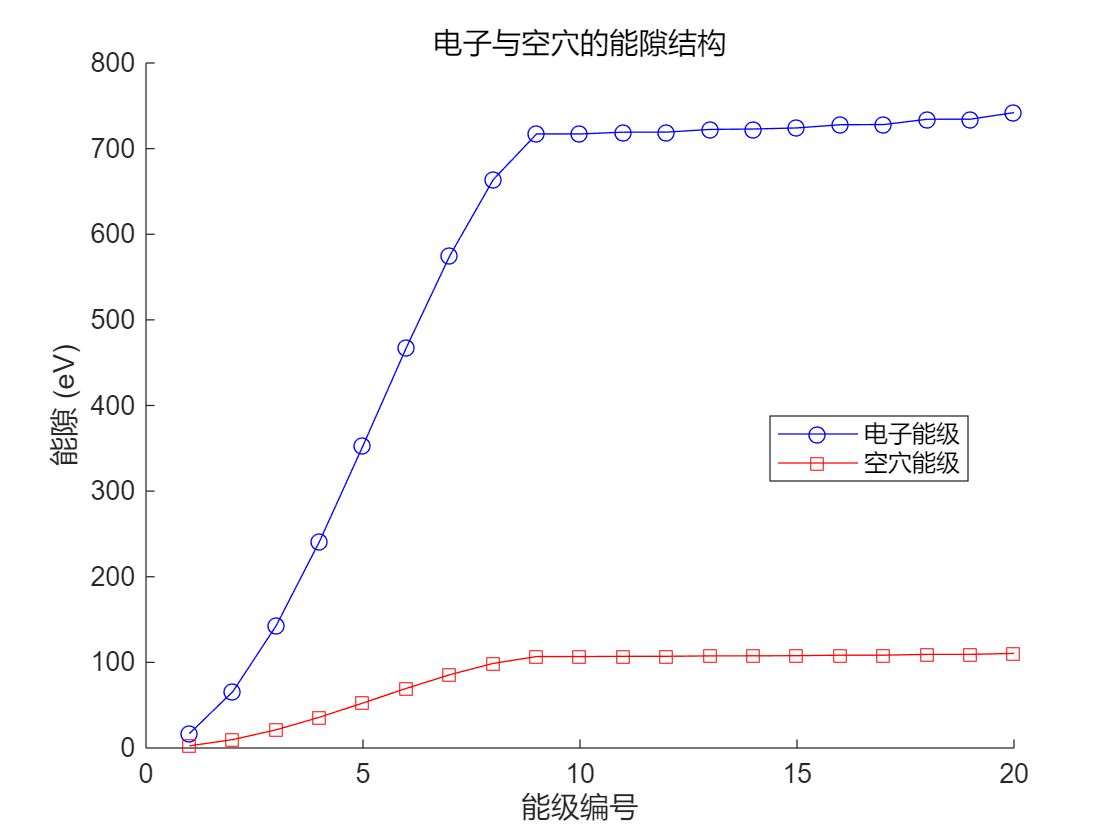

% Plot energy gap
num_levels = 20;
figure;
hold on;
plot(1:num_levels, eigenvalues_e(1:num_levels), 'b-o', 'DisplayName', '电子能级');
plot(1:num_levels, eigenvalues_h(1:num_levels), 'r-s', 'DisplayName', '空穴能级');
xlabel('能级编号');
ylabel('能隙 (eV)');
title('电子与空穴的能隙结构');
legend(Location="best");
hold off;